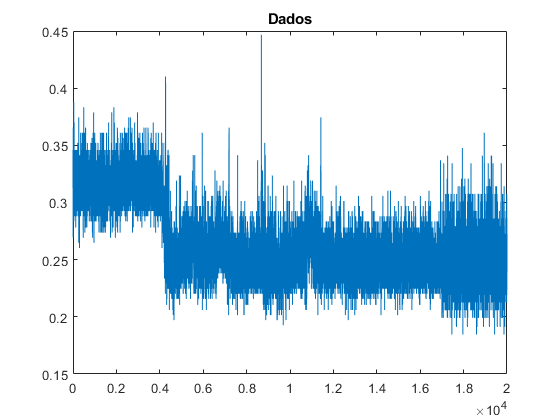

% Importe os dados
Y = load('dados');

% Plote os dados
figure(1);
plot(Y);
title('Dados');

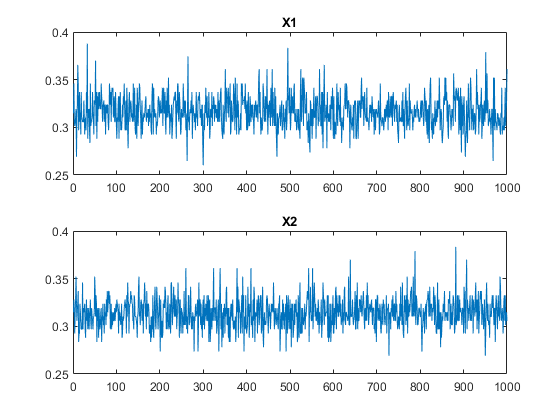


% Determine os segmentos de dados
X1 = Y(1:1000);
X2 = Y(1001:2000);
X3 = Y(2001:3000);

% Calcule a média e o desvio padrão de cada segmento
mu1 = mean(X1);
mu2 = mean(X2);
mu3 = mean(X3);
sigma1 = std(X1);
sigma2 = std(X2);
sigma3 = std(X3);

% Realize o teste de médias com 1000 amostras
ttest = ttest2(X1,X2,'alpha',0.05);

% Plote os dados utilizados no teste
figure(2);
subplot(2,1,1);
plot(X1);
title('X1');
subplot(2,1,2);
plot(X2);
title('X2');


% Plote a cdf usada no teste com o valor da estatística de teste
figure(3);
% Obtem a estatística de teste
ttest_statistic = ttest.statistic(1);

Dot indexing is not supported for variables of this type.


% Calcula a cdf da estatística de teste
cdf = tpdf(ttest_statistic,1000);



plot(cdf);
hold on;
plot(ttest.statistic,1);
title('CDF usada no teste');

% Calcule o p-valor
pvalue = 2*cdf(ttest.statistic);

% Realize o teste de médias com 10 amostras
ttest10 = ttest2(X1(1:10),X2(1:10),'alpha',0.05);

% Plote os dados utilizados no teste
figure(4);
subplot(2,1,1);
plot(X1(1:10));
title('X1');
subplot(2,1,2);
plot(X2(1:10));
title('X2');

% Plote a cdf usada no teste com o valor da estatística de teste
figure(5);
cdf = tpdf(ttest10.statistic,10);
plot(cdf);
hold on;
plot(ttest10.statistic,1);
title('CDF usada no teste');

% Calcule o p-valor
pvalue10 = 2*cdf(ttest10.statistic);

% Realize o teste de médias com 50 amostras
ttest50 = ttest2(X1(1:50),X2(1:50),'alpha',0.05);

% Plote os dados utilizados no teste
figure(6);
subplot(2,1,1);
plot(X1(1:50));
title('X1');
subplot(2,1,2);
plot(X2(1:50));
title('X2');

% Plote a cdf usada no teste com o valor da estatística de teste
figure(7);
cdf = tpdf(ttest50.statistic,50);
plot(cdf);
hold on;
plot(ttest50.statistic,1);
title('CDF usada no teste');

% Calcule o p-valor
pvalue50 = 2*cdf(ttest50.statistic);

% Imprima os resultados
disp('Teste com 1000 amostras');
disp('Estatística de teste:');
disp(ttest.statistic);
disp('P-valor:');
disp(pvalue);
disp('Teste com 10 amostras');
disp('Estatística de teste:');
disp(ttest10.statistic);
disp('P-valor:');
disp(pvalue10);
disp('Teste com 50 amostras');
disp('Estatística de teste:');
disp(ttest50.statistic);
disp('P-valor:');
disp(pvalue50);
